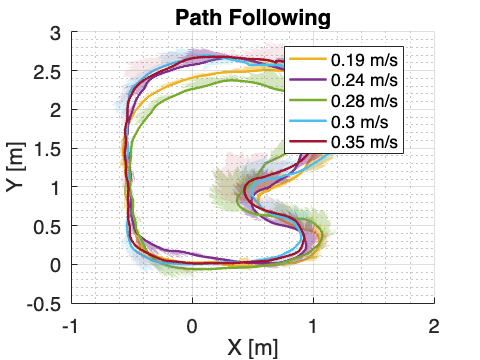

clear; clc; close all;

addpath("utils/")
rec3Chicane = [3490, 3900];

% Identified Laps (Manually Defined)
rec1Lap = [4550, 6720];  
rec2Lap = [2080, 4060]; 
rec3Lap = [1390, 3420]; 
rec4Lap = [100, 1700];  
rec5Lap = [980, 2330; 3585, 5090]; 
rec6Lap = [2140, 3500]; 
rec7Lap = [2220, 3360]; 

lapIntervalsAll = {rec1Lap, rec2Lap, rec3Lap, rec4Lap, rec5Lap(1,:), rec6Lap, rec7Lap};
nRecordings = numel(lapIntervalsAll);  % Ensure consistency

% Initial conditions for each lap
initialTheta = deg2rad([-108; -10; 160; -127; -145; -20;-35]);
initialX = [0.78; 0.5; 0.245; 0.9; 0.6; 0.45; 0.7];
initialY = [1.86; 2.67; 0; 1.65; 1.3; 2.6; 2.6];

trajectoryCell = cell(nRecordings, 1);
trgvels = cell(nRecordings, 1);  % Use a cell array for strings
lapstats = cell(nRecordings, 1);


% Define colors for the trajectories and filled areas
trajColors = lines(nRecordings); % Generates distinct colors
fillOpacities = linspace(0.7, 0.1, nRecordings); % Gradually decrease fill opacity

% Reconstruct all trajectories
for recIdx = 3:nRecordings    
    dataPath = sprintf('DataSets/rec%d.csv', recIdx);
    [~, timedelta, data] = parseDataSet(dataPath);
    dt = mean(timedelta) * 1e-9;  % Convert nanoseconds to seconds
    
    config = struct();
    lapInterval = lapIntervalsAll{recIdx};
    config.start = lapInterval(1);
    config.stop = lapInterval(2);
    config.heading_subsample = 30;
    config.heading_scale = 0.7;
    config.theta0 = initialTheta(recIdx);
    config.x0 = initialX(recIdx);
    config.y0 = initialY(recIdx);
    
    [x_rec, y_rec, theta_rec, linvel_rec, stats_rec] = mapping(data, dt, config);
    trgvels{recIdx} = num2str(stats_rec.trgtVel+" m/s");  % Store as string in a cell array
    lapstats{recIdx} = stats_rec.time;
    
    % Compute the "course" (heading-based velocity projection)
    coursex = cos(theta_rec) .* linvel_rec;
    coursey = sin(theta_rec) .* linvel_rec;

    % Close the trajectory loop
    x_rec(end+1) = x_rec(1);
    y_rec(end+1) = y_rec(1);
    coursex(end+1) = coursex(1);
    coursey(end+1) = coursey(1);
    
    trajectoryCell{recIdx} = [x_rec, y_rec, coursex, coursey];
    lapstats{recIdx} = stats_rec;
end

%% Plot all the trajectories
fig = figure;
ax = axes(fig);
hold on;

for recIdx = 3:nRecordings
    traj = trajectoryCell{recIdx};

    % Plot trajectory with distinct colors
    plot(traj(:,1), traj(:,2), 'Color', trajColors(recIdx, :), 'LineWidth', 2);
    heading = 
    % Create filled area to represent heading uncertainty
    x_fill = [traj(:,1); flipud(traj(:,1) + traj(:,3))];
    y_fill = [traj(:,2); flipud(traj(:,2) + traj(:,4))];
    fill(x_fill, y_fill, trajColors(recIdx, :), 'FaceAlpha', fillOpacities(recIdx), 'EdgeColor', 'none');

    % Store legend entry
end
legendNames = [trgvels(3), "", trgvels(4), "", trgvels(5), "", trgvels(6), "", trgvels(7)];
legend(legendNames, 'Location', 'best', 'FontSize', 14);
% Customize the plot for publication quality
xlabel('X [m]', 'FontSize', 16);
ylabel('Y [m]', 'FontSize', 16);
title('Path Following', 'FontSize', 22);
grid on; grid minor;
set(gca, 'FontSize', 16);

hold off;
addpath("utils/")
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, "Path Following.pdf");
exportgraphics(fig, filepath);


lapstats{3:end}

ans = struct with fields:
      trgtVel: 0.1900
      vel_dev: 0.1057
      vel_var: 0.0112
    steer_dev: 1.0103
    steer_var: 1.0207
         time: 40.5900


ans = struct with fields:
      trgtVel: 0.2400
      vel_dev: 0.1103
      vel_var: 0.0122
    steer_dev: 1.2158
    steer_var: 1.4781
         time: 31.9900


ans = struct with fields:
      trgtVel: 0.2800
      vel_dev: 0.0965
      vel_var: 0.0093
    steer_dev: 1.2230
    steer_var: 1.4958
         time: 27


ans = struct with fields:
      trgtVel: 0.3000
      vel_dev: 0.1024
      vel_var: 0.0105
    steer_dev: 1.2942
    steer_var: 1.6750
         time: 27.2000


ans = struct with fields:
      trgtVel: 0.3500
      vel_dev: 0.1183
      vel_var: 0.0140
    steer_dev: 1.2838
    steer_var: 1.6480
         time: 22.8000



axis equal;
animateTrajectory(x,y,theta,linvel,dt,config)

